% ----------------------------------------------
% Accountant methods
% last updated: 05/23/2022
% ----------------------------------------------
% First, we obtaining discrete distribution pair (po,qo)
% The method used here are: FFT-Fei, FFT-Gopi, Saddlepoint Accountant, Moments Accountant.
% ----------------------------------------------

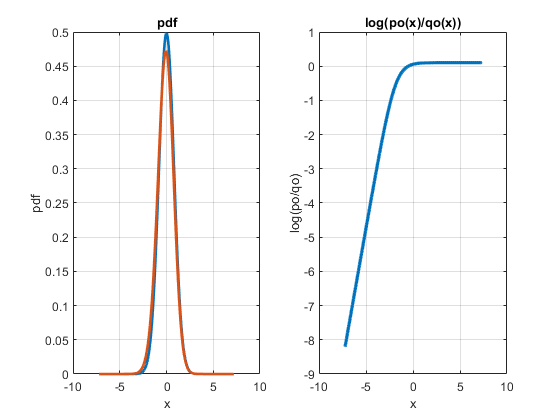

clear
close all

% let the show begin!
% note that for a single composition, we can compute the Egamma directly.

composition = 500;
sen = 1;
subsampling = 1e-1;
sigma=0.8;
noise_type=1;

switch noise_type
    case 0
        load(sprintf("cactus_pdf_d%.1f_L2_%.1f.mat",sen,sigma^2))
        x_grid=x(1:end-sen*n);
        x_max=max(x_grid);
        x_step_size=1/n;
        po=p(1:end-sen*n)/x_step_size;
        qo= subsampling*p(sen*n+1:end)/x_step_size+(1-subsampling)*po;
    otherwise
        % guassian
        if noise_type==1
            f = @(x) 1/sqrt(2*pi)/sigma*exp(-1/2*x.^2/sigma^2);

            pq = @(x)1./(1-subsampling+subsampling.*exp(-1/2/sigma^2*(2*x+1)));
        else
            % laplace
            b=sigma/sqrt(2);
            f = @(x) 1/2/b*exp(-abs(x)/b);
        end
        % Take samples, and its shift/subsampled.
        x_max = sigma*9;
        x_step_size = 1e-4;
        n = 1/x_step_size;
        x_grid = -x_max:x_step_size:x_max;
        po = f(x_grid);
        qo = subsampling*f(x_grid+sen)+(1-subsampling)*po;
        po=po';
        qo=qo';

        pq_list=pq(x_grid)';

end

% this right here is a hack! This code is not properly accounting for the tails of the distribution
po = po/(x_step_size*sum(po));
qo = qo/(x_step_size*sum(qo));


KL=sum(po.*log(po./qo))*x_step_size;

figure
subplot(1,2,1);
plot(x_grid,po,"LineWidth",2,'DisplayName','p(x)')
hold on
plot(x_grid,qo,"LineWidth",2,'DisplayName','q(x)')
xlabel('x','FontSize',15)
ylabel('pdf','FontSize',15)
title('pdf','FontSize',15)
grid on

subplot(1,2,2);
plot(x_grid,log(po./qo),'.',"LineWidth",2)
xlabel('x','FontSize',15)
ylabel('log(po/qo)','FontSize',15)
title('log(po(x)/qo(x))','FontSize',15)
grid on


Eg=@(gamma) sum(x_step_size*max(0,po-gamma*qo));
% Eg=@(gamma) sum(x_step_size*po.*max(0,1-gamma./pq_list));
% Eg = @(gamma) 1/2*(erfc((-1+2*sigma^2*log(gamma))/2/sqrt(2)/sigma)-...
%     gamma*erfc((1+2*sigma^2*log(gamma))/2/sqrt(2)/sigma));


% Next, we sample the Egamma curve uniformly.
if noise_type==1
    
    if subsampling~=1
        rate=po./qo;
        gamma_max=max(rate);
        gamma_min=min(rate(po>1e-15));
    else
        gamma_max=min(10,exp(composition*KL*3));
    end
else
    rate=po./qo;
    gamma_max=max(rate(1:end-n*sen));
end

gamma_step=(gamma_max-gamma_min)/1e4;
gamma_grid=gamma_min:gamma_step:gamma_max;

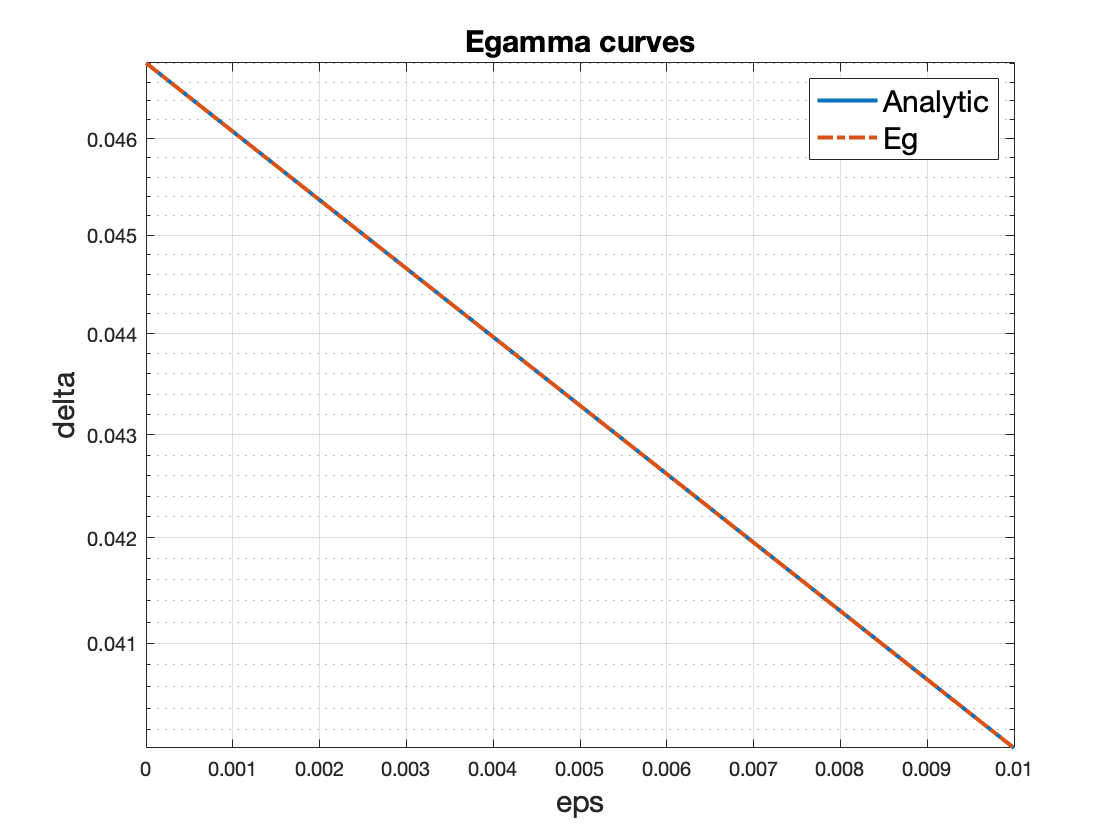

% Now we consider Gopi's FFT approach, start with Gaussian mech.

% Algorithm 2 (DiscretizePRV), 

f_x = @(x) 1/sqrt(2*pi)/sigma*exp(-1/2*x.^2/sigma^2);

xy= @(l) -(2*sigma^2*log(1/exp(l)/subsampling-1/subsampling+1)+sen^2)/2/sen;
f_l = @(l) f_x(xy(l))*sigma^2/sen/(1-(1-subsampling)*exp(l));

l_step_size=1e-4;
l_grid=log(gamma_min):l_step_size:log(gamma_max);
fLAnalytic_array =arrayfun(f_l,l_grid);
fLAnalytic_array=fLAnalytic_array/sum(fLAnalytic_array);
delta_Analytic_bd = @(eps) sum(fLAnalytic_array.*max(0,1-exp(eps-l_grid)));



figure
eps_test0=0:1e-2:0.01;
arrayfun(delta_Analytic_bd,eps_test0);
semilogy(eps_test0,arrayfun(delta_Analytic_bd,eps_test0),'-',...
    'LineWidth',2,'DisplayName','Analytic');
hold on
semilogy(eps_test0,arrayfun(Eg,exp(eps_test0)),'-.',...
    'LineWidth',2,'DisplayName','Eg');
legend('FontSize',15);
xlabel('eps','FontSize',15)
ylabel('delta','FontSize',15)
title('Egamma curves','FontSize',15)
grid on



left=min(l_grid);
right=max(l_grid);
l_grid_padding = composition*left:l_step_size:composition*right;

% Compute FFT bound from (p3,q3)
pO=fLAnalytic_array;

% We can actually avoid all FFT shifting (and normalization) if we zero-pad at the end of 
% the vector, rather than on both sides. In fact the fft function will automatically do this
% if we just add a second argument with the desired length
pOFFT = fft(pO,length(l_grid_padding));
cfFFT_array = pOFFT.^composition;
fLConvFFT_array0 = ifft(cfFFT_array);
fLConvFFT_array0 = max(0,fLConvFFT_array0);
sum(fLConvFFT_array0)

ans = 1.0000

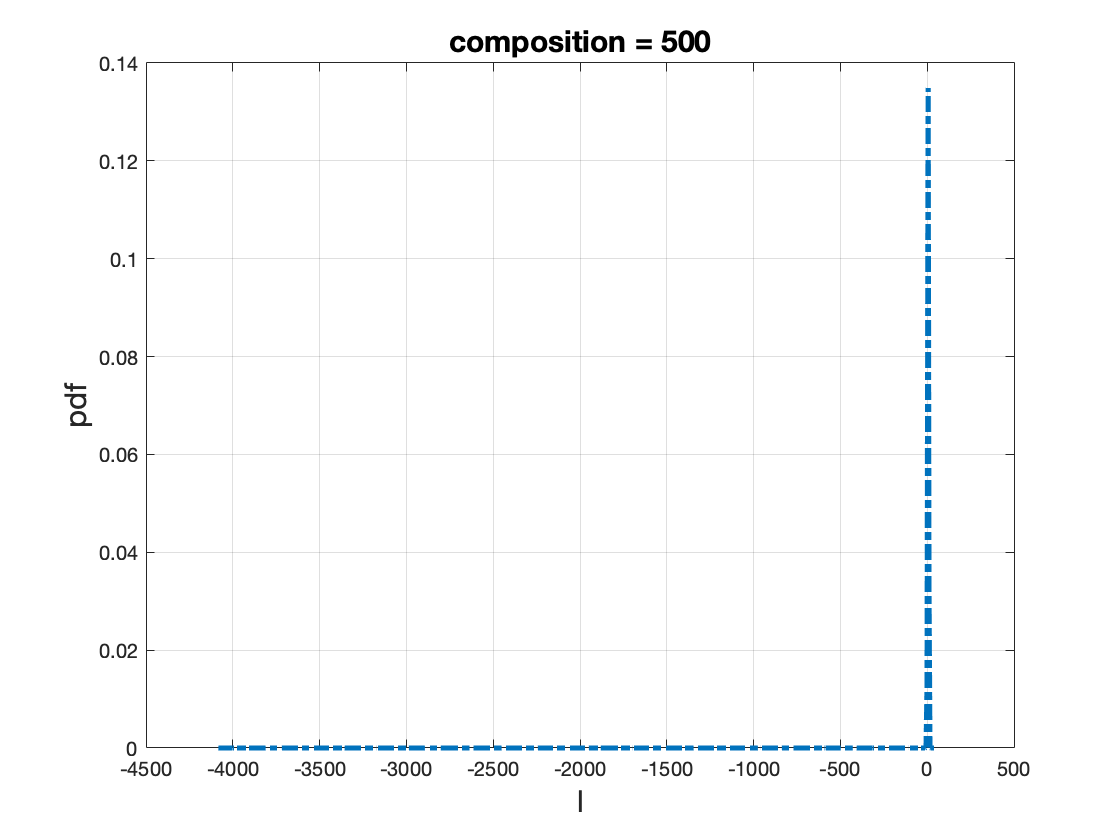

figure
plot(l_grid_padding,abs(fLConvFFT_array0)/l_step_size,'-.',...
    'LineWidth',2,'DisplayName','upper bd');
xlabel('l','FontSize',15)
ylabel('pdf','FontSize',15)
title(sprintf('composition = %d',composition),'FontSize',15)
grid on

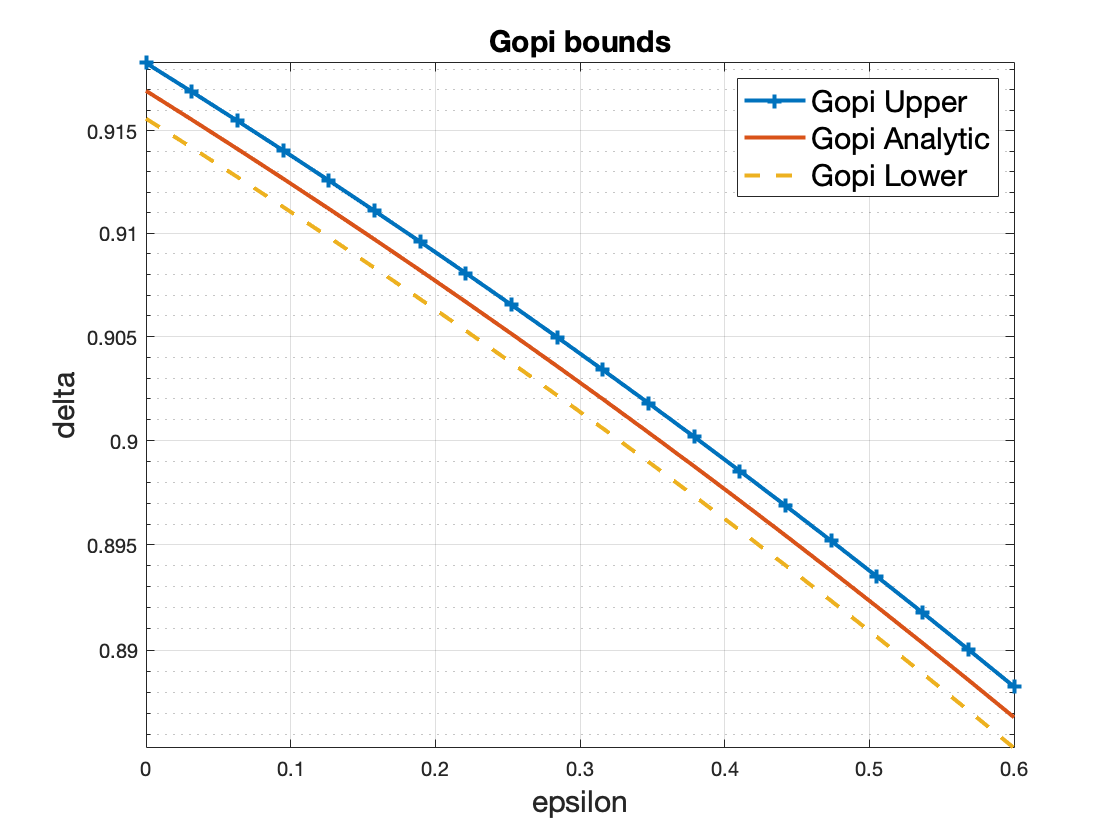



delta_err_rate=1e-3;
eps_err = 0.01;

% the FFT curve is given as follows.
delta_GopiFFT_bd = @(eps) sum(fLConvFFT_array0.*max(0,1-exp(eps-l_grid_padding)));
delta_GopiFFT_upper = @(eps) delta_GopiFFT_bd(eps-eps_err)*(1+delta_err_rate);
delta_GopiFFT_lower = @(eps) delta_GopiFFT_bd(eps+eps_err)*(1-delta_err_rate);



% figure
% eps_grid=linspace(0,0.6,20);
% 
% delta_GopiFFT_upper_array = arrayfun(delta_GopiFFT_upper,eps_grid);
% semilogy(eps_grid,delta_GopiFFT_upper_array,'-+',...
%     "LineWidth",2,'DisplayName','Gopi Upper')
% hold on
% 
% delta_GopiFFT_bd_array = arrayfun(delta_GopiFFT_bd,eps_grid);
% semilogy(eps_grid,delta_GopiFFT_bd_array,'-',...
%     "LineWidth",2,'DisplayName','Gopi Analytic');
% hold on
% 
% delta_GopiFFT_lower_array = arrayfun(delta_GopiFFT_lower,eps_grid);
% semilogy(eps_grid,delta_GopiFFT_lower_array,'--',...
%     "LineWidth",2,'DisplayName','Gopi Lower');
% xlabel('epsilon','FontSize',15)
% ylabel('delta','FontSize',15)
% title('Gopi bounds','FontSize',15)
% legend('FontSize',15)
% grid on

% ----------------------------------------------
% FFT-Fei:
% ----------------------------------------------
% Step 1: Obtain a E-gamma curve on gamma_grid via function Eg(gamma_grid) -> Eg_grid
%
% Step 2(a): Obtain distribution pair upper bounding Eg_grid -> (p2,q2)
%       (b): Use (eps_grid,p2) as a random variable L_low 
%       (c): Perform FFT and iFFT to get convoluted (l_grid_padding,fLConvFFT_array2)
%       (d): Compute the Egamma_upper()
%
% Step 3(a): Obtain distribution pair lower bounding Eg_grid -> (p3,q3)
%       (b): Use (eps_grid,p3) as a random variable L_low 
%       (c): Perform FFT and iFFT to get convoluted (l_grid_padding,fLConvFFT_array3)
%       (d): Compute the Egamma_lower()
% ----------------------------------------------




Step 1

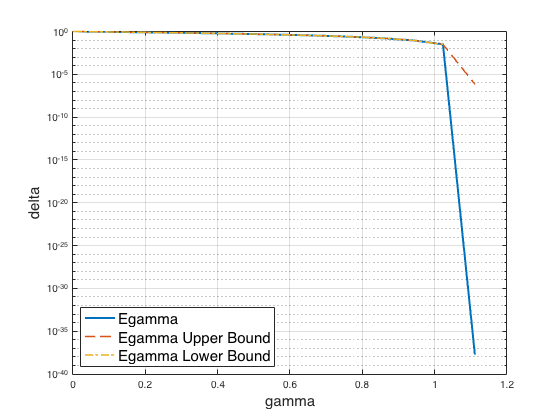


Eg_grid = arrayfun(Eg,gamma_grid); % samples uniform on Egamma curve
Eg_grid = [Eg_grid,Eg_grid(end)];


% Step Test

% q is the sencond order derivative 
% we didn't divide gamma_step twice as this is discrete!
q1 = diff(Eg_grid,2)/gamma_step; 
p1 = q1.* gamma_grid(2:end); % p is propotional to q
q1=[q1,0];
p1=[p1,1-sum(p1)];
p1=[p1,0];
q1=[q1,1-sum(q1)];

% We use Egamma1 for verifing the result.
Egamma1 = @(gamma) sum(max(0,p1-gamma*q1));


% Now, instead of sample evenly on gamma, we sample uniformly on epsilon = log(gamma)
% Few things to note:
% (1) For gamma starts from 0, epsilon starts from some negetive value.
% (2) Since the sample is even on log(gamma), we also need dynamic step
% size on gamma. As the samples are dense on the left and loose on the
% right.

eps_max = log(gamma_max);
eps_min = log(gamma_min);
eps_step_size = 1e-3;
eps_grid = eps_min:eps_step_size:eps_max; % define the lattice on epsilon
gamma_grid2 = exp(eps_grid); % convert it to gamma, now the gamma samples are uniform on log


% Again, we use Egamma2 for verifing the result, it should be an upper
% bound of the true Egamma curve.
[p2,q2] = pq_upper(Eg,gamma_grid2);


% Lastly, we get a lower bounding discrete model (p3,q3).
Egslope = @(gamma) -x_step_size*sum(qo(po>gamma*qo));
[p3,q3] = pq_lower(Eg,Egslope,gamma_grid2);


figure

semilogy(gamma_grid2,arrayfun(Eg,gamma_grid2),...
    "LineWidth",2,"DisplayName","Egamma");
hold on

% Eg_array_upper1 = arrayfun(Egamma1,gamma_grid_test);
% semilogy(gamma_grid2,Eg_array_upper1,'--D',...
%     "LineWidth",1.5,'DisplayName','EgammaUpper-gamma',...
%     'MarkerIndices',1:ceil(length(gamma_grid_test)/20):length(gamma_grid_test));
% hold on

Egamma_upper = @(gamma) sum(max(0,p2-gamma*q2));
Eg_array_upper2 = arrayfun(Egamma_upper,gamma_grid2);
semilogy(gamma_grid2,Eg_array_upper2,'--',...
    "LineWidth",1.5,'DisplayName','Egamma Upper Bound');
hold on

Egamma_lower = @(gamma) sum(max(0,p3-gamma*q3));
Eg_array_lower = arrayfun(Egamma_lower,gamma_grid2);
semilogy(gamma_grid2,Eg_array_lower,'-.',...
    "LineWidth",1.5,'DisplayName','Egamma Lower Bound');

xlabel("gamma",'FontSize',15);
ylabel("delta",'FontSize',15);
legend('Location', 'southwest','FontSize',15);
grid on;

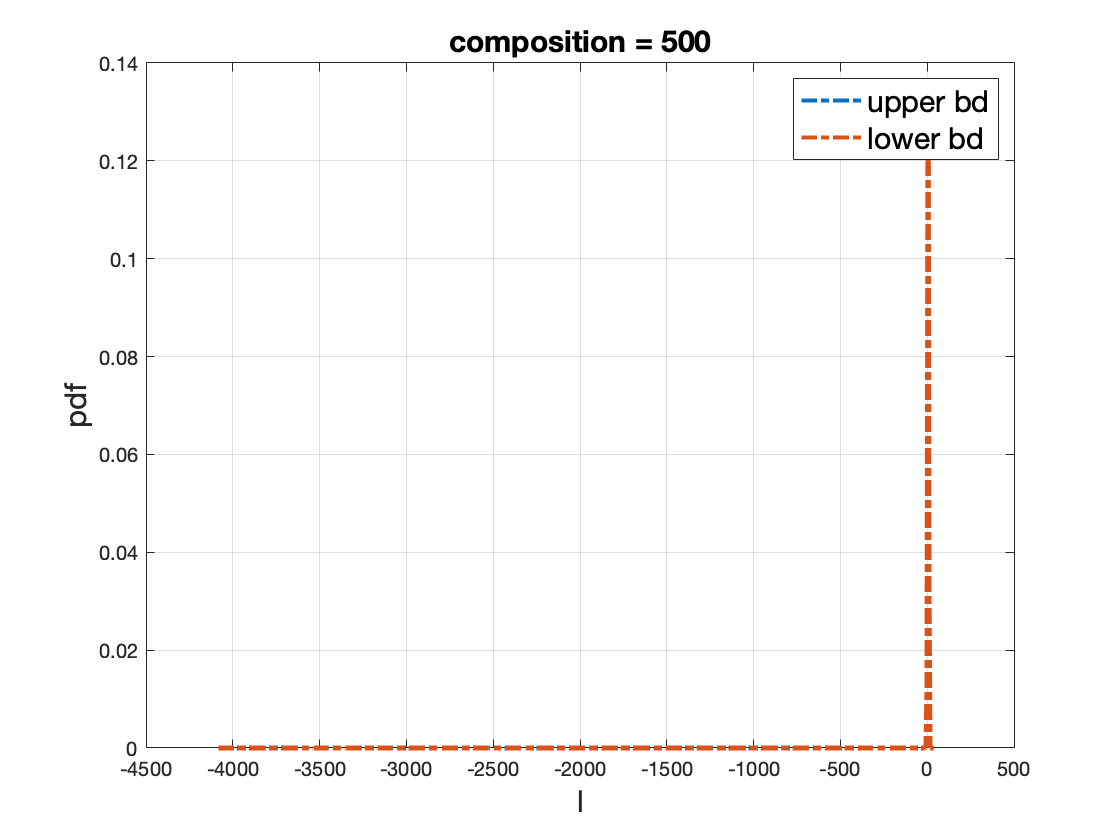




% Before applying the FFT, we first pad the privacy loss pdf as we will use
% circular FFT in the code.
l_step_size = eps_step_size;
left=min(eps_grid);
right=max(eps_grid);
l_grid_padding = composition*left:l_step_size:composition*right;


% Step 3

% Compute FFT bound from (p3,q3)
pO=p3;
% We can actually avoid all FFT shifting (and normalization) if we zero-pad at the end of 
% the vector, rather than on both sides. In fact the fft function will automatically do this
% if we just add a second argument with the desired length
pOFFT = fft(pO,length(l_grid_padding));
cfFFT_array = pOFFT.^composition;
fLConvFFT_array3 = ifft(cfFFT_array);
fLConvFFT_array3 = max(0,fLConvFFT_array3);

% the FFT curve is given as follows.
delta_FFT_lower_bd = @(eps) sum(fLConvFFT_array3.*max(0,1-exp(eps-l_grid_padding)));


% Step 2

% Compute FFT bound from (p2,q2)
pO=p2(2:end-1);

% There's a minor problem with the upper bounding model, since the last value has q2(end)=0 but
% p2(end)>0. This correspondings to an infinite value of L, which doesn't show up in the grid.
% We can deal with this by slicing off the last value, then adding back to delta the probability 
% that any of the compositions happens to hit the last value. This occurs with probability
% 1-(1-p2(end))^composition
pOFFT = fft(pO,length(l_grid_padding));
cfFFT_array = pOFFT.^composition;
fLConvFFT_array2 = ifft(cfFFT_array);
fLConvFFT_array2 = max(0,fLConvFFT_array2);

% the FFT curve is given as follows.
delta_FFT_upper_bd = @(eps) sum(fLConvFFT_array2.*max(0,1-exp(eps-l_grid_padding)))+(1-(1-p2(end))^composition);



figure
plot(l_grid_padding,abs(fLConvFFT_array2)/l_step_size,'-.',...
    'LineWidth',2,'DisplayName','upper bd');
hold on
plot(l_grid_padding,abs(fLConvFFT_array3)/l_step_size,'-.',...
    'LineWidth',2,'DisplayName','lower bd');
legend('FontSize',15)
xlabel('l','FontSize',15)
ylabel('pdf','FontSize',15)
title(sprintf('composition = %d',composition),'FontSize',15)
grid on


% The whole idea here is the following: we first derive the approximate
% (P,Q) pair which has the same E-gamma curve but also has nice bijictive
% properties that leads to the (approximate) privacy loss random variable,
% then we are ready to apply the FFT to compute the convoluted pdf to deal
% with compositions.

% % For testing, we can start with a privacy loss random variable pdf.

% close all
% clear
% 
% composition = 1;
% 
% sigma=1;
% 
% % For Gaussian
% fL=@(l) 1/sigma/sqrt(2*pi).*exp(-1/2*(l/sigma).^2);
%  
% l_min=-10;
% l_step_size=0.01;
% l_max=10;
% l_grid=l_min:l_step_size:l_max;
% fL_array=fL(l_grid);

% Here we setup the grids for testing.
eps_max_test=composition*KL*10

eps_max_test = 54.2658

eps_max_test=10;
eps_grid_test = linspace(1e-10,eps_max_test,20);

a_max=10;
a_min=1e-5;


% With FFT delta curve as a baseline, now we derive the saddle-point
% curves. Basically there are two approaches, one is directly from the
% orignal noise distributions, one is from the convoluted pdf (FFT).

fL_array = p2(2:end-1)./l_step_size;
l_grid=eps_grid;

EexptL=@(t) sum(l_step_size*fL_array.*exp(t*l_grid));

fLTilt=@(t) exp(t*l_grid).*fL_array/EexptL(t);

K = @(t,n) n*log(EexptL(t));

K1 = @(t,n) n*sum(l_step_size*fL_array.*l_grid.*exp(t*l_grid))./EexptL(t);

K2 = @(t,n) n*(sum(l_step_size*fL_array.*l_grid.^2.*exp(t*l_grid))./EexptL(t)-K1(t,1).^2);

gmax= @(t) t.^t./(t+1).^(t+1);

C=6;
ELTilt = @(t) sum(l_step_size*l_grid.*fLTilt(t));
T = @(t,n) sum(l_step_size*fLTilt(t).*abs(l_grid-ELTilt(t)).^3)*n;

delta27 = @(eps,t,n) exp(K(t,n)-eps*t)*(1/sqrt(2*pi*K2(t,n))/t/(t+1));
error = @(t,n) 2*gmax(t)*T(t,n)*t*(t+1)/K2(t,n)*C;

t_list=zeros(length(eps_grid_test),1);
for i =1:length(eps_grid_test)
    tic
    t_list(i)=fminbnd(@(t) delta27(eps_grid_test(i),t,composition).*(1+error(t,composition)),a_min,a_max);
    toc
end

delta_27=zeros(length(eps_grid_test),1);
for i = 1:length(eps_grid_test)
    delta_27(i)=delta27(eps_grid_test(i),t_list(i),composition);
end
error_array=arrayfun(@(t) error(t,composition),t_list);

% Alternative, we can directly compute the K functions with original
% distributions.

% if noise_type~=0
%     x_step_size2=1/200;
%     x_grid2=-8:x_step_size2:8;
%     ps = f(x_grid2)*x_step_size2;
%     qs = subsampling*f(x_grid2+sen)*x_step_size2+(1-subsampling)*ps;
%     ps=ps';
%     qs=qs';
% else
%     shift_steps = ceil(sen*n);
%     ps=p(1:end-shift_steps);
%     qs= subsampling*p(shift_steps+1:end)+(1-subsampling)*ps;
% end
ps=po*x_step_size;
qs=qo*x_step_size;

mgf = @(t) sum(ps.*(ps./(qs+1e-20)).^t);
logmgf = @(t) log(sum(ps.*(ps./(qs+1e-20)).^t));
KB = @(t,n) n*logmgf(t);
K1B = @(t,n) n*sum(ps.*log(ps./(qs+1e-20)).*(ps./(qs+1e-20)).^t)/mgf(t);
K2B = @(t,n) n*(sum(ps.*(log(ps./(qs+1e-20))).^2.*(ps./(qs+1e-20)).^t)/mgf(t)-K1B(t,1).^2);

C=6;
ELtilt3 = @(t) sum(ps.*(log(ps./(qs+1e-20))).^3.*(ps./(qs+1e-20)).^t)/mgf(t); %!!!
TB = @(t,n) n*abs(ELtilt3(t)-(K1B(t,1)).^3-3*K1B(t,1).*K2B(t,1));

delta27B = @(eps,t,n) exp(KB(t,n)-eps*t)*(1/sqrt(2*pi*K2B(t,n))/t/(t+1));
errorB = @(t,n) 2*gmax(t)*TB(t,n)*t*(t+1)/K2B(t,n)*C;

t_listB=zeros(length(eps_grid_test),1);
for i =1:length(eps_grid_test)
    tic
    t_listB(i)=fminbnd(@(t) delta27B(eps_grid_test(i),t,composition).*(1+errorB(t,composition)), a_min,a_max);
    toc
end

% figure
% t_gridtest=0.01:0.1:5
% plot(t_gridtest,arrayfun(@(t) delta27B(0.01,t,composition).*(1+errorB(t,composition)),t_gridtest))

[t_list,t_listB]
delta_27B=zeros(length(eps_grid_test),1);
for i = 1:length(eps_grid_test)
    delta_27B(i)=delta27B(eps_grid_test(i),t_listB(i),composition);
end

error_arrayB=arrayfun(@(t) errorB(t,composition),t_listB);

% a_grid= linspace(a_min,max(t_list),20);
% figure;
% plot(a_grid,arrayfun(@(t) K(t,composition),a_grid),"LineWidth",1.5,"DisplayName","K(t)");
% hold on
% plot(a_grid,arrayfun(@(t) K1(t,composition),a_grid),"LineWidth",1.5,"DisplayName","K'(t)");
% hold on
% plot(a_grid,arrayfun(@(t) K2(t,composition),a_grid),"LineWidth",1.5,"DisplayName","K''(t)");
% hold on
% plot(a_grid,arrayfun(@(t) KB(t,composition),a_grid),'--',"LineWidth",1.5,"DisplayName","K(t) Alt");
% hold on
% plot(a_grid,arrayfun(@(t) K1B(t,composition),a_grid),'--',"LineWidth",1.5,"DisplayName","K'(t) Alt");
% hold on
% plot(a_grid,arrayfun(@(t) K2B(t,composition),a_grid),'--',"LineWidth",1.5,"DisplayName","K''(t) Alt");
% xlabel("t","FontSize",13)
% title(sprintf('cgf with derivatives, compositions=%d',composition))
% legend("FontSize",13)
% grid on

% In this block, we no longer relay on the approximate (P,Q) pair, rather
% we use the original noise distributions to obtain the moment/cumulant
% generating functions.
 
% Saddlepoint
logmgf = @(t) log(sum(ps.*((ps./(qs))).^t));
fSP = chebfun(@(t) composition*logmgf(t)-log(t)-log(1+t), [1e-10,10],'splitting','on');
fSP_diff = diff(fSP);
fSP_hess = diff(fSP,2);
delta_SP_array = zeros(length(eps_grid_test),1);
for i=1:length(eps_grid_test)
    eps = eps_grid_test(i);
    x0 = roots(fSP_diff-eps);
    if isempty(x0)
        delta_SP_array(i)=0;
    else
        temp = exp(fSP(x0)-eps*x0)/sqrt(abs(fSP_hess(x0)))/sqrt(2*pi);
        delta_SP_array(i)=temp;
    end
end

% logmgf = @(t) log(sum(ps.*((ps./(qs+1e-20))).^t));
% fSP = chebfun(@(t) composition*logmgf(t), [1e-30,10],'splitting','on');
% fSP_diff = diff(fSP);
% fSP_hess = diff(fSP,2);
% delta_SP_array = zeros(length(eps_grid_test),1);
% for i=1:length(eps_grid_test)
%     eps = eps_grid_test(i);
%     x0 = roots(fSP_diff-eps);
%     if isempty(x0)
%         delta_SP_array(i)=0;
%     else
%         temp = exp(fSP(x0)-eps*x0)/sqrt(abs(fSP_hess(x0)))/sqrt(2*pi)/x0/(x0+1);
%         delta_SP_array(i)=temp;
%     end
% end


% Plancherel

a = 0.01;
lims =  [-50,50];
mgf = @(t) (sum(ps.*((ps./(qs+1e-30))).^t));
f2 = chebfun(@(t) (mgf(a+1i*t)), lims,'splitting','on');
filter = chebfun(@(t) 1/((a+1i*t).*(a+1i*t+1)),lims,'splitting','on' );
t = chebfun('t',lims,'splitting','on');
delta_cf_array = zeros(length(eps_grid_test),1);
for i=1:length(eps_grid_test)
    eps = eps_grid_test(i);
    delta_cf_array(i) = real(exp(-eps*a)*sum((f2.^composition)*exp(-eps*(1i*t))*filter)/(2*pi));
end


% Moments accountant

alpha_max = 50; %maximum lambda in MGF
fMA = chebfun(@(t) logmgf(t), [0,alpha_max],'splitting','on'); 
alpha_grid = chebfun(@(t) t, [0,alpha_max],'splitting','on'); 
delta_MA_array = zeros(length(eps_grid_test),1);
for i=1:length(eps_grid_test)
    eps = eps_grid_test(i);
    delta_MA_array(i) = exp(min(composition*fMA-eps*alpha_grid));
end


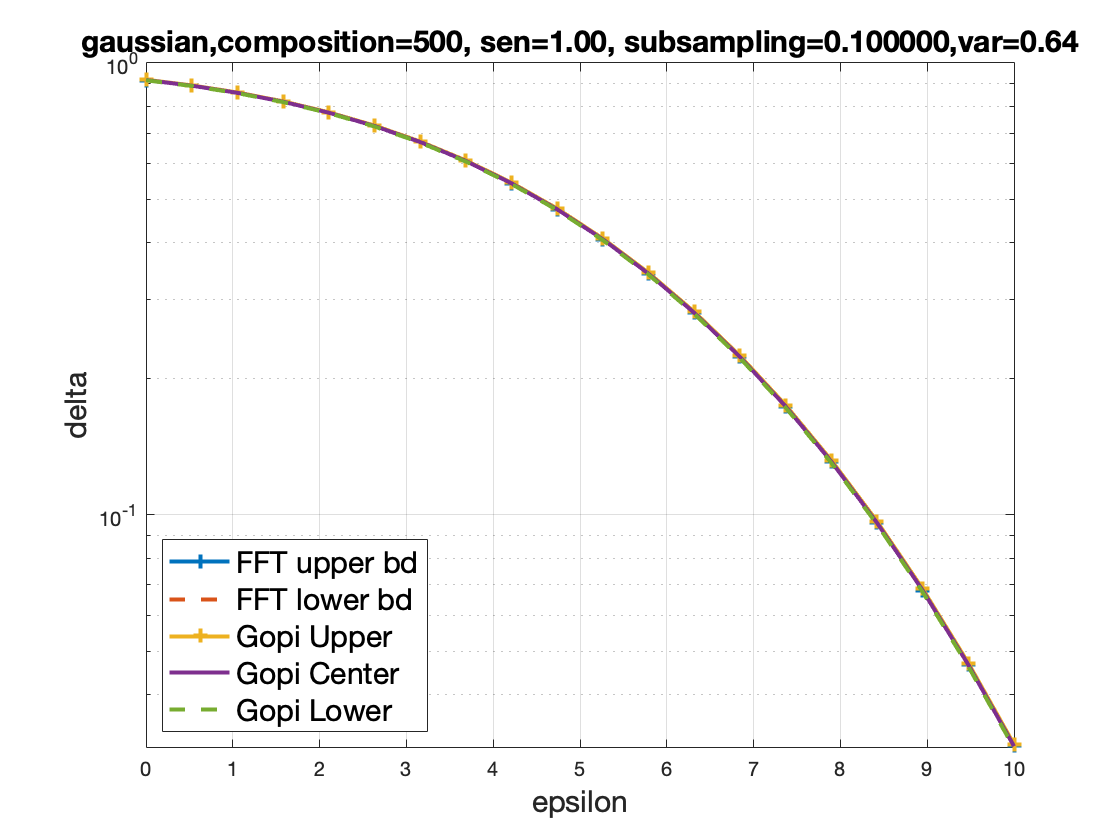


figure

% semilogy(eps_grid_test,delta_MA_array,'-.',...
%     "LineWidth",2,"DisplayName","Moments Accountant")
% hold on

% if composition==1
%     semilogy(eps_grid_test,arrayfun(Eg,exp(eps_grid_test)),'-.',...
%         "LineWidth",2,"DisplayName","Original Egamma")
%     hold on
% 
%     semilogy(eps_grid_test,arrayfun(Egamma2,exp(eps_grid_test)),'--o',...
%         "LineWidth",1.5,"DisplayName","Upper Egamma",'MarkerIndices',1:20:length(eps_grid_test))
%     hold on
% end

filename = sprintf('fft_epsilon.csv');
csvwrite(filename,eps_grid_test);

fft_upper = abs(arrayfun(delta_FFT_upper_bd,eps_grid_test));
semilogy(eps_grid_test,fft_upper,'-+',...
    "LineWidth",2,"DisplayName","FFT upper bd")
hold on
filename = sprintf('fft_upper.csv');
csvwrite(filename,fft_upper);

fft_lower = abs(arrayfun(delta_FFT_lower_bd,eps_grid_test));
semilogy(eps_grid_test,fft_lower,'--',...
    "LineWidth",2,"DisplayName","FFT lower bd")
hold on
filename = sprintf('fft_lower.csv');
csvwrite(filename,fft_lower);

delta_GopiFFT_upper_array = arrayfun(delta_GopiFFT_upper,eps_grid_test);
semilogy(eps_grid_test,delta_GopiFFT_upper_array,'-+',...
    "LineWidth",2,'DisplayName','Gopi Upper')
hold on

delta_GopiFFT_bd_array = arrayfun(delta_GopiFFT_bd,eps_grid_test);
semilogy(eps_grid_test,delta_GopiFFT_bd_array,'-',...
    "LineWidth",2,'DisplayName','Gopi Center');
hold on

delta_GopiFFT_lower_array = arrayfun(delta_GopiFFT_lower,eps_grid_test);
semilogy(eps_grid_test,delta_GopiFFT_lower_array,'--',...
    "LineWidth",2,'DisplayName','Gopi Lower');
xlabel('epsilon','FontSize',15)
ylabel('delta','FontSize',15)
title('Gopi bounds','FontSize',15)
legend('FontSize',15)

% semilogy(eps_grid_test,delta_cf_array,'-.',...
%     "LineWidth",2,"DisplayName","Plancherel")
% hold on
% 
% semilogy(eps_grid_test,delta_SP_array,'-.',...
%     "LineWidth",2,"DisplayName","Saddlepoint")
% hold on

% semilogy(eps_grid_test,delta_27,'--D',...
%     "LineWidth",1.5,"DisplayName","Base Term")
% hold on
% 
% semilogy(eps_grid_test,delta_27.*(1+error_array),'--D',...
%     "LineWidth",1.5,"DisplayName","Base Term with Error")
% hold on

% semilogy(eps_grid_test,abs(delta_27B),'-+',...
%     "LineWidth",1.5,"DisplayName","Base Term (Alt)")
% hold on
% 
% semilogy(eps_grid_test,abs(delta_27B.*(1+error_arrayB)),'-+',...
%     "LineWidth",1.5,"DisplayName","Base Term with Error (Alt)")
% hold on

% 5*sqrt(K2B(0,composition))
noise_names=["cactus" "gaussian" "laplace"];
title(sprintf('%s,composition=%d, sen=%.2f, subsampling=%f,var=%.2f',noise_names(noise_type+1),composition,sen,subsampling,sigma^2))
xlabel("epsilon",'FontSize',15)
ylabel('delta','FontSize',15)
legend('FontSize',15,'Location','Southwest')
grid on